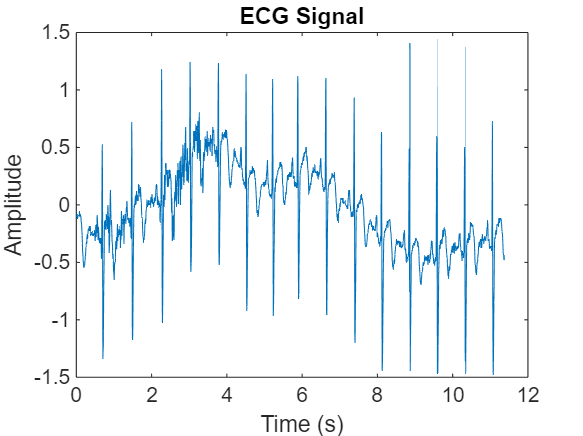

clear, close all
load wecg;
fs=180;
t=(1:length(wecg))/fs;

figure;
plot(t,wecg);
xlabel('Time (s)');
ylabel('Amplitude');
title('ECG Signal');

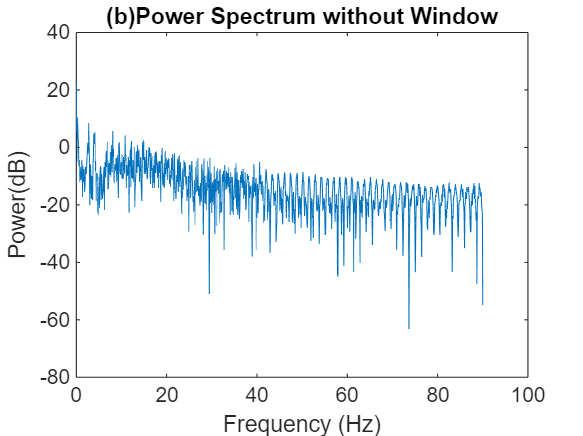


nfft = 2^nextpow2(length(wecg));
wecg_freq=fft(wecg,nfft);
P2=abs(wecg_freq).^2 / length(wecg);
P1=P2(1:nfft/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = fs*(0:(nfft/2))/nfft;

figure,
plot(f,10*log10(P1))
xlabel('Frequency (Hz)');
ylabel('Power(dB)');
title('(b)Power Spectrum without Window');
hold on

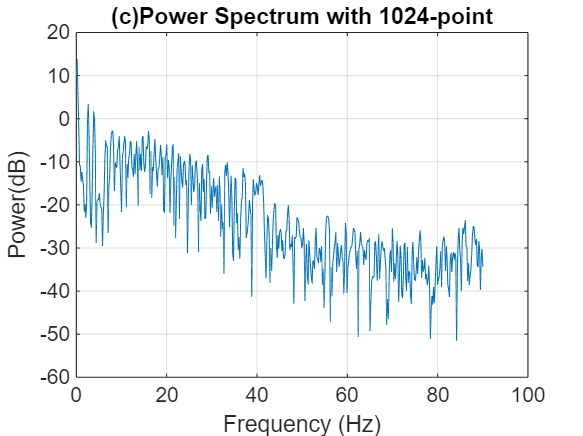


N=1024;
x=wecg(1:N);
WF=hamming(N);
wecg_trunc=x.*WF;

nfft2 = 2^nextpow2(N); 
X = fft(wecg_trunc, nfft2);
P2 = abs(X).^2 / N;
P1 = P2(1:nfft2/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = fs*(0:(nfft2/2))/nfft2;

figure;
plot(f, 10*log10(P1)); 
xlabel('Frequency (Hz)');
ylabel('Power(dB)');
title('(c)Power Spectrum with 1024-point');
grid on;